bag= rosbag('london_track_demo1.bag');


WaypointTopic= select(bag, 'Topic', '/sim/track');
WaypointMsg = readMessages(WaypointTopic,'DataFormat','struct');

path_x=[];
path_y=[];

for i= 1:length(WaypointMsg)
    path_x= [path_x, WaypointMsg{i,1}.Points.X];
    path_y= [path_y, WaypointMsg{i,1}.Points.Y];
end

path_edge= [path_x' path_y'];
%csvwrite('road_data_Cplus.csv',path_edge)

path_center= xlsread("london_track.xlsx");

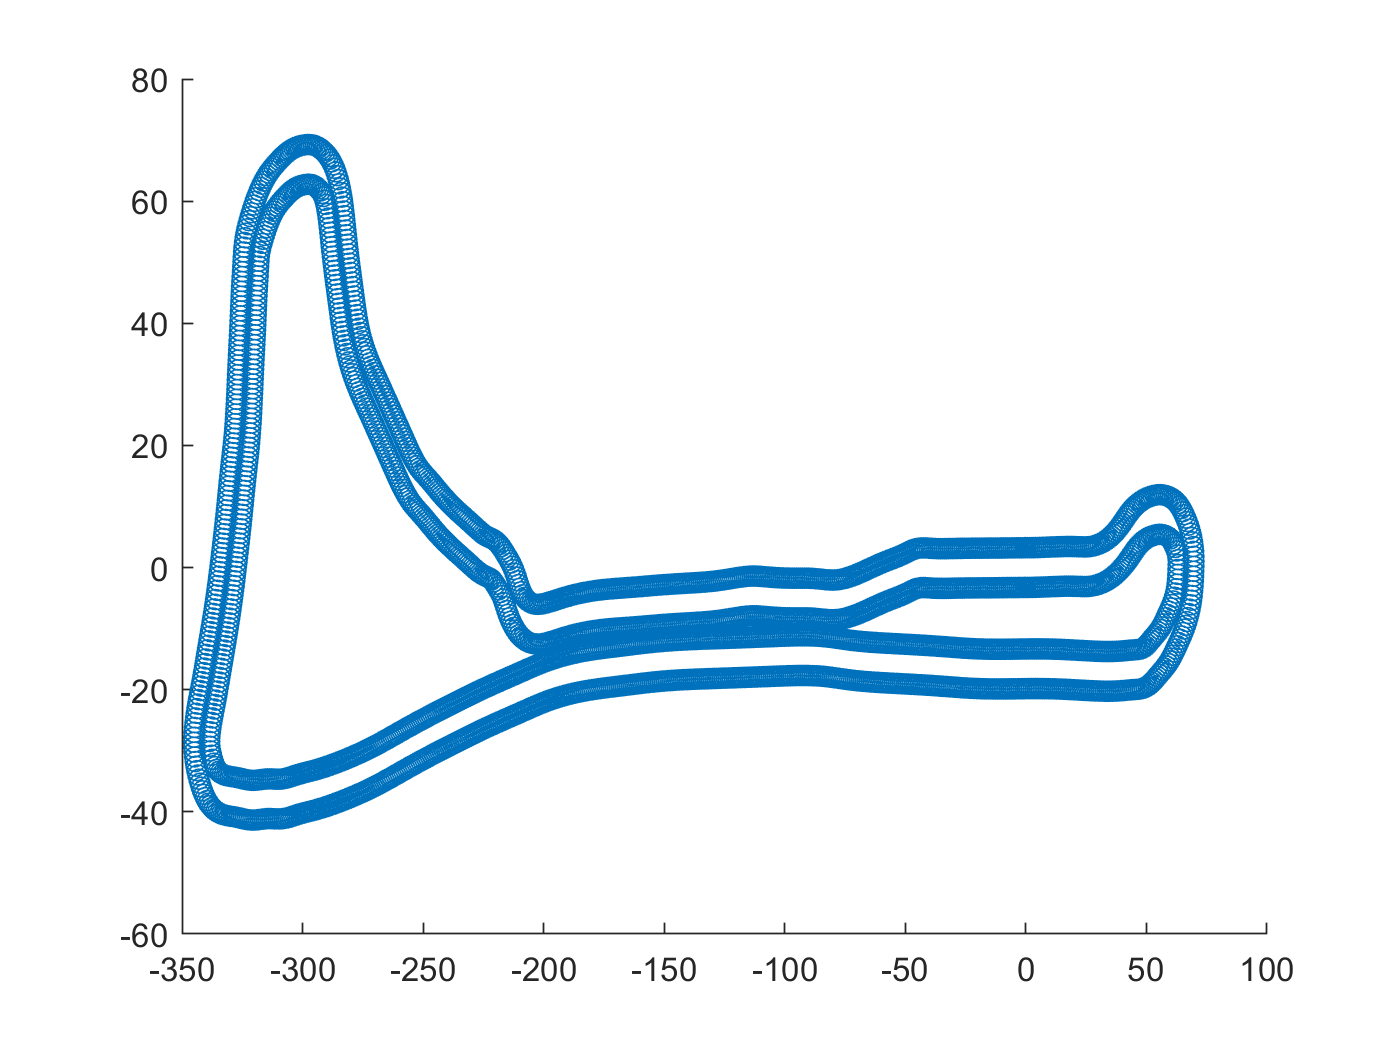

close all;
figure;
scatter(path_x, path_y);
% scatter(center_x,center_y);
hold on;
%scatter(path_center(:,1), path_center(:,2));
hold off

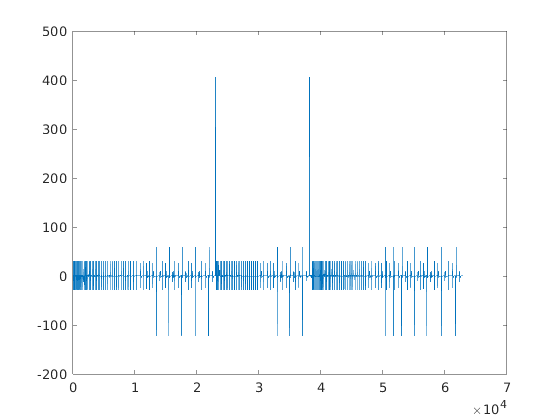

% k=[];
% for i=1:(length(path_x)-1)
%     k= [k; (path_y(i+1)-path_y(i))/(path_x(i+1)-path_x(i))];
% end
% 
% plot(1:length(k), k)

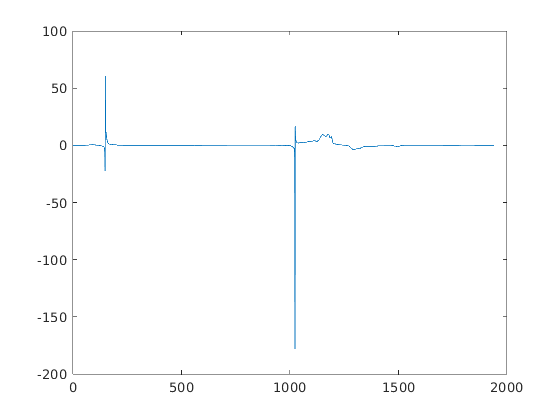

k=[];

for i=1:(length(path_center)-1)
    k= [k; (path_center(i+1,2)-path_center(i,2))/(path_center(i+1,1)-path_center(i,1))];
end

plot(1:length(k), k)